# Project 2: Motion Detection via Communication Signals

**张怡程 马文骁 高进 陈嘉祺**

## **Introduction**

#### **    Principles of Montion Detection**

    Moving objects reflects signal and causes time delay due to distance difference and frequency shift due to Doppler Effect of the radiation signal. The signal derectly comes from the illuminator is called reference signal, and the reflected one is called surveillance signal. We can analyze the two signals and find the time delay and frequency shift caused by the object and thus deriving the motion of it. Assume the transmitted signal to be $x\left(t\right)$, the reference signal to be $y_{\mathrm{ref}} \left(t\right)$ and surveillance signal to be $y_{\mathrm{sur}} \left(t\right)$. We can get


$$y_{\mathrm{ref}} \left(t\right)=\alpha x\left(t-\tau_1 \right),{\;\;\;\;\;y}_{\mathrm{sur}} \left(t\right)=\beta x\left(t-\tau_2 \right)e^{\mathrm{j2}\pi f_d t}$$


    Where α and β stand for the  attenuation factor due to transmission, $\tau \;$stands for the time delay. Due to Doppler Effect


$$\tau_i =\frac{s_i }{c},\;\;\;\;\;f_d =\frac{vf_c }{c}$$


    Where $f_d$ is the Doppler frequency shift.

####     Cross-Correlation(ambiguity function)

Ambiguity function is aimed to estimate the relation of two signals. Here is it's defination:


$$\mathrm{Cor}\left(\tau ,f\right)=\int_t^{t+T} y_{\mathrm{sur}} \left(t\right)y_{\mathrm{ref}}^{\ast } \left(t-\tau \right)e^{-\mathrm{j2}\pi \mathrm{ft}} \mathrm{dt}$$


where $y_{\mathrm{sur}} \left(t\right)$ is the complex envelope of the signal received in the surveillance channel, $y_{\mathrm{ref}} \left(t\right)$ is a (cleaned) replica of the transmitted signal, $\tau$ is the potential TDOA of the target echo signal, and $f$ is the potential corresponding bistatic Doppler. 

    And the maximum value of $\mathrm{Cor}\left(\tau ,f\right)$, the corresponding variables of which are the kinematic information we get:


$$\left(\hat{\tau} ,\hat{f_d } \right)=\arg_{\tau ,f} \;\mathrm{maxCor}\left(\tau ,f\right)$$


#### **    Time domain processing of signals**

    The signal is always transmitted at a higher frequency, which means we need to convert the target signal to the frequency centered on 0 Hz.Then filter out the high-frequency signal through the low-pass filter.

    The process of converting signal to the frequency centered on 0 Hz is called digital downconverter.  By the properies of fourier transform, we can achieve the expected result through the following formula.


$$y\left(t\right)=x\left(t\right)e^{-\mathrm{j2}\pi f_{\mathrm{ddc}} t}$$
 

    where $f_{\mathrm{ddc}}$ is the central frequency of the target signal fragment.

    To filter out the high-frequency signal, we choose the 20 levels Butterworth low-pass filter:

## Result and Analysis

Task 1 

addpath('rawData\data_1\')

load('rawData\data_1\data_1.mat');

For convenience, we first only deal with 0.01s's data.

seq_sur1=seq_sur(1:(length(seq_sur)/50));
seq_ref1=seq_ref(1:(length(seq_sur)/50));
duration1=0.01;
fs=f_s;

The LPF filter we will use has this effect:

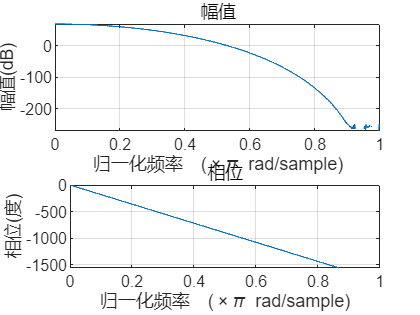

freqz(butter(20,9e6/(fs/2),'low'));

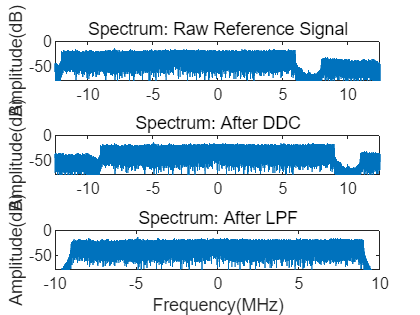

y1rd=sigAfterDDC(seq_ref1,fs);
y1rf=sigAfterLPF(seq_ref1,fs);

plotSpectrum(seq_ref1,fs,1,3,'Spectrum: Raw Reference Signal')
plotSpectrum(y1rd,fs,2,3,'Spectrum: After DDC')
plotSpectrum(y1rf,fs,3,3,'Spectrum: After LPF')

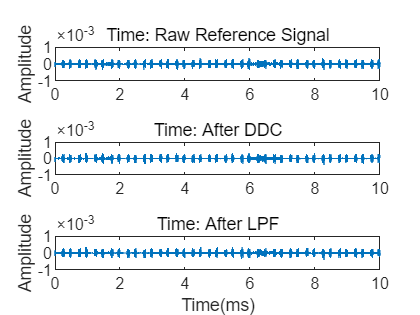


plotTimeSig(seq_ref1,fs,1,3,'Time: Raw Reference Signal')
plotTimeSig(y1rd,fs,2,3,'Time: After DDC')
plotTimeSig(y1rf,fs,3,3,'Time: After LPF')


y1sf=sigAfterLPF(seq_sur1,fs);

Basical function

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function plotTimeSig(x,fs,a,n,Title)
    if a==1
        figure
    end
    t=xTime(x,fs);
    subplot(n,1,a),plot(t.*1e3,real(x)),title(Title)
    ylabel("Amplitude"),ylim([-1e-3,1e-3])%注意这里的ylim和PPT不一样
    if a==n
        xlabel("Time(ms)")
    end
end

function plotSpectrum(x,fs,a,n,Title)
    N=length(x);
    H=fftshift(fft(x));
    f=(-N/2:N/2-1)*fs/N;
    if a==1
        figure
    end
    subplot(n,1,a),plot(f./10^6,20*log10(abs(H))),title(Title)
    ylabel('Amplitude(dB)'),ylim([-80,0])
    if a==n
        xlabel('Frequency(MHz)')
    end
end

Task 1 function: DDC and filter

function x_moved=sigAfterDDC(x,fs)
    f_ddc=-3e6;
    t=xTime(x,fs);
    x_moved=x.*exp(-1j*2*pi*f_ddc.*t);
end

function x_filtered=sigAfterLPF(x,fs)
    f_ddc=-3e6;
    bandwidth=9e6;
    t=xTime(x,fs);
    x=x.*exp(-1j*2*pi*f_ddc.*t);
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
end